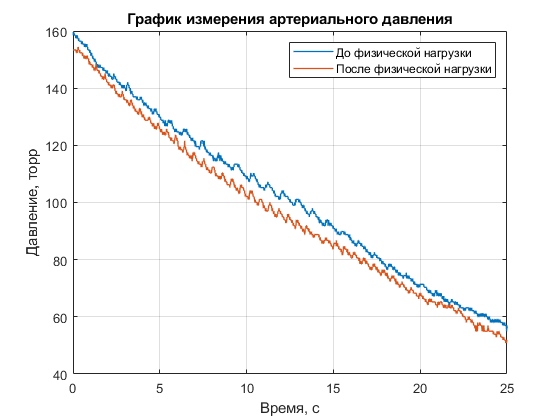

dt = 0.01;

adcBefore = fscanf(fopen('data/data_before.txt'), '%d');
tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore));
pBefore = polyval(c, adcBefore);

adcAfter = fscanf(fopen('data/data_after.txt'), '%d');
tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter));
pAfter = polyval(c, adcAfter);

pFigure = figure("Name", 'Графики давления', 'NumberTitle', "off");

plot(tBefore, pBefore, tAfter, pAfter, 'LineWidth', 1);
legend('До физической нагрузки', "После физической нагрузки");

grid on;
xlim([0, 25]);

xlabel('Время, с');
ylabel('Давление, торр');
title('График измерения артериального давления');

saveas(pFigure, 'Давление.png')